addpath("functions/");

# Simulation

save_to_file = true;


L = 50;
wait = 10e2;

save_cycles = 5;
steps = 10e3;

model = @BTW;




% First iteration
if exist('z','var') && exist('avalanche_sizes','var');
	[event_size,z] = model(L,steps,0,z);
	avalanche_sizes = [avalanche_sizes; event_size];
elseif exist('avalanche_sizes','var');
	[event_size,z] = model(L,steps,wait);
	avalanche_sizes = [avalanche_sizes; event_size];
else
	[avalanche_sizes,z] = model(L,steps,wait);
end

% Save to file if the box was checked
timestamp = datestr(now,'mm-dd_HH-MM');
model_str = func2str(model);
filename = sprintf('data/%s_data_%s.mat',model_str,timestamp);


if save_to_file
	s = struct("avalanche_sizes",avalanche_sizes,"z",z,"L",L, ...
		"steps",steps,"wait",wait,"save_cycles",save_cycles, ...
		"z_c",3,"q",4,"model_str",model_str);
	save(filename, "-fromstruct",s);
end

% Post-thermalization loop
parfor iter = 1:save_cycles-1

	[event_size,~] = model(L,steps,0,z)

	s = struct("event_size",event_size,"timestamp",timestamp,"iter",iter);
	save(sprintf("data/temp_%s_%d",timestamp,iter),"-fromstruct",s);

	sprintf("Completed save cycle %d out of %d",iter+1,save_cycles)

end

ans = 
    "Completed save cycle 2 out of 5"
ans = 
    "Completed save cycle 3 out of 5"
ans = 
    "Completed save cycle 5 out of 5"
ans = 
    "Completed save cycle 4 out of 5"


avalanche_sizes = consolidate_temp_data(avalanche_sizes,"data/",timestamp);

ans = "Consolidated and deleted temp_08-28_20-52_1.mat"

ans = "Consolidated and deleted temp_08-28_20-52_2.mat"

ans = "Consolidated and deleted temp_08-28_20-52_3.mat"

ans = "Consolidated and deleted temp_08-28_20-52_4.mat"

if save_to_file
	s = struct("avalanche_sizes",avalanche_sizes);
	save(filename, "-fromstruct",s,"-append");
end

# Post processing and plotting

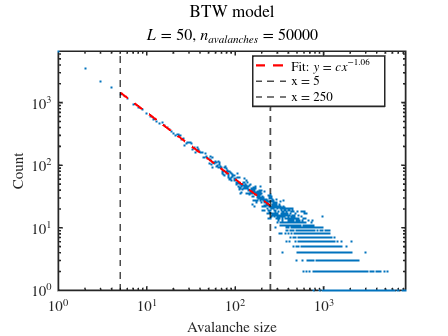

addpath("functions/");

if ~exist('avalanche_sizes','var'); load("/home/francesco/Documents/UNI/Sistemi complessi/SOC simulation/data/Manna_data_08-28_20-49.mat"); end

[sizes, count] = postprocess_data(avalanche_sizes);
subtitle = "$L = "+L+"$, $n_{avalanches} = "+numel(avalanche_sizes)+"$";
[fig,tau] = plot_avalanches(sizes,count,5,250,model_str+" model",subtitle);